# [Final Exam] 

## Problem 1

### Subproblem 1

"Use the following code to generate a data set. Plot the data.  "

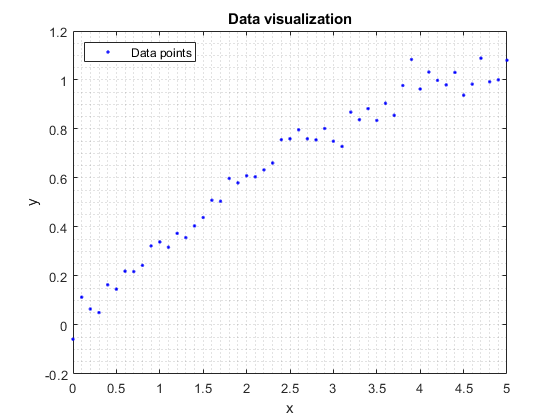

clear all;close all;clc;
x = [0:0.1:5]';
y = sin(2*pi*0.05*x) + 0.05*randn(size(x));
plot(x,y,'b.');
xlabel('x');
ylabel('y');
grid minor
hold on
title('Data visualization')
legend('Data points','Location','northwest','Orientation','horizontal')

### Subproblem 2

"Do the linear regression and plot the model with the original data "

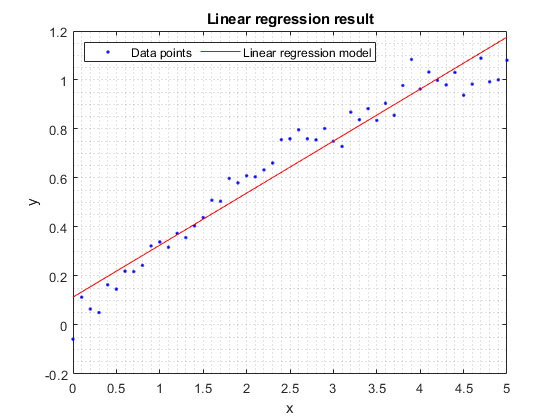

figure
plot(x,y,'b.');
xlabel('x');
ylabel('y');
grid minor
hold on
A = [ones(size(x,1),1) x];
theta = inv(A'*A)*A'*y;
xa = linspace(0,5);
ya = theta(1) + theta(2).*xa;
plot(xa,ya,'r-')
legend('Data points','Linear regression model','Location','northwest','Orientation','horizontal')
title('Linear regression result')

### Subprolem 3

"Do the nonlinear regression using polynomials up to the 2nd order and plot the model with the original data `"`

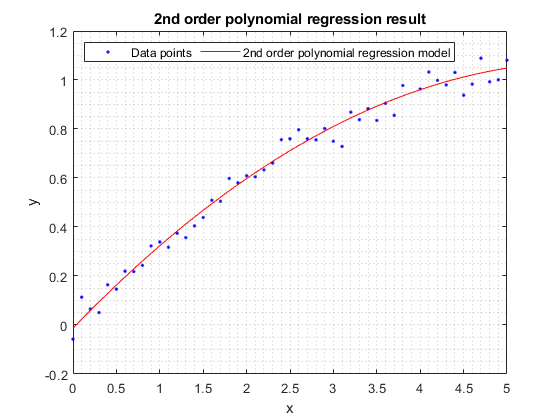

A = [ones(size(x,1),1) x x.^2];
theta = inv(A'*A)*A'*y;
ya = theta(1) + theta(2)*xa + theta(3)*xa.^2;
figure;
plot(x,y,'b.');
xlabel('x');
ylabel('y');
grid minor
hold on
plot(xa,ya,'r-')
legend('Data points','2nd order polynomial regression model','Location','northwest','Orientation','horizontal')
title('2nd order polynomial regression result')

### Subprolem 4

"Use the following code to generate a data set. Plot the data.  "

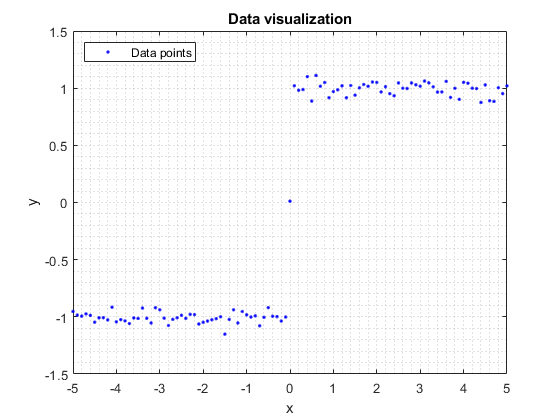

clear all;close all;clc;
x = [-5:0.1:5]';
y = zeros(size(x));
y(1:50) = -1;
y(52:end) = 1;
y = y + 0.05*randn(size(y));

figure
plot(x,y,'b.')
xlabel('x');
ylabel('y');
grid minor
title('Data visualization')
legend('Data points','Location','northwest','Orientation','horizontal')

### Subprolem 5

"Do the nonlinear regression using the following three functions and plot the model with the original data."

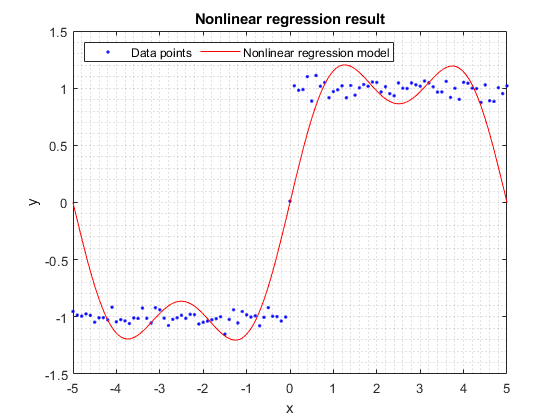


sin_1 = @(x) sin(2*pi*x/10);
sin_2 = @(x) sin(4*pi*x/10);
sin_3 = @(x) sin(6*pi*x/10);

A = [];
for i = 1:size(x,1)
    A = [A; sin_1(x(i)) sin_2(x(i)) sin_3(x(i)) ];
end

func = @(theta)norm(A*theta-y)^2;
% options = optimset('MaxFunEvals',10000);
theta_opt = fminsearch(func, ones(3,1));
xa = linspace(-5,5,1000);

for i = 1:length(xa)
    ya(i) = [sin_1(xa(i)) sin_2(xa(i)) sin_3(xa(i))]*theta_opt;
end
figure
plot(x,y,'b.')

xlabel('x');
ylabel('y');
grid minor
hold on
plot(xa,ya,'r-')
title('Nonlinear regression result')
legend('Data points','Nonlinear regression model','Location','northwest','Orientation','horizontal')

## Problem 2

### Subproblem 1

"Do the k-means clustering to separate the data into three groups. Plot the result "

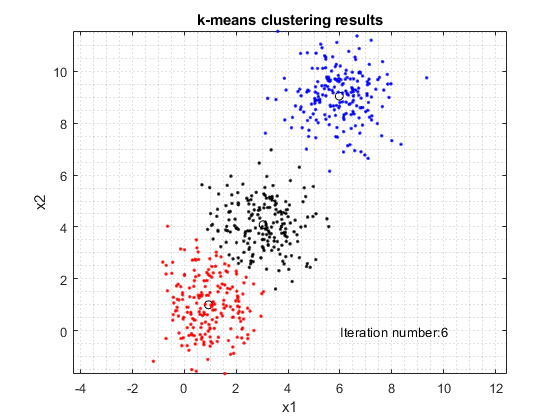

clear all;close all;clc
n = 200;
data1 = mvnrnd([1,1], eye(2), n);
data2 = mvnrnd([3,4], eye(2), n);
data3 = mvnrnd([6,9], eye(2), n);
data_all = [data1; data2; data3];
plot(data_all(:,1), data_all(:,2), '.')
axis equal
hold on
xlabel('x1')
ylabel('x2')
grid minor
title('k-means clustering results')


% k-means implementation
k = 3;
m = 3*randn(k,2) + 6; % initial mean

fig0 = plot(m(:,1), m(:,2), 'ko');
fig0.XDataSource = 'm(:,1)';
fig0.YDataSource = 'm(:,2)';
fig4 = text(0,10,'');

max_iter = 100;
mean_threshold = 0.01;
distance_m = zeros(k,1);
group_idx = zeros(size(data_all,1),1);
m_updated = zeros(size(m));

for i = 1:max_iter
    % for each data point, determine group index
    for j = 1:size(data_all,1)
        for s = 1:k
            distance_m(s) = norm(data_all(j,:) - m(s,:));
            % distance from cluster to this data point
        end
        [min_value, group_idx(j)] = min(distance_m);
    end
    for j = 1:k
        m_updated(j,:) = mean(data_all(group_idx == j,:));
    end
    if norm(m(:) - m_updated(:)) < mean_threshold
        m = m_updated;
        break;
    else
        m = m_updated;
        delete(fig4);
    end
    % Visualzation
    fig1 = plot(data_all(group_idx==1,1), data_all(group_idx ==1,2),'b.');
    fig1.XDataSource = 'data_all(group_idx==1,1)';
    fig1.YDataSource = 'data_all(group_idx==1,2)';

    fig2 = plot(data_all(group_idx==2,1), data_all(group_idx ==2,2),'r.');
    fig2.XDataSource = 'data_all(group_idx==2,1)';
    fig2.YDataSource = 'data_all(group_idx==2,2)';
    
    fig3 = plot(data_all(group_idx==3,1), data_all(group_idx ==3,2),'k.');
    fig3.XDataSource = 'data_all(group_idx==3,1)';
    fig3.YDataSource = 'data_all(group_idx==3,2)';
    
    fig4= text(6,0,['Iteration number:' num2str(i)]);
    refreshdata
%     pause(1)

end

disp('Done')

Done


### Subproblem 2

"Starting from the following mean values, the MATLAB code we used in the class does not work.

Explain (a) why, (b) discuss how it can be resolved, and (c) write MATLAB code to implement it "

clear all;close all;clc
n = 200;
data1 = mvnrnd([1,1], eye(2), n);
data2 = mvnrnd([3,4], eye(2), n);
data3 = mvnrnd([6,9], eye(2), n);
data_all = [data1; data2; data3];
plot(data_all(:,1), data_all(:,2), '.')
axis equal
hold on
xlabel('x1')
ylabel('x2')
grid minor
title('k-means clustering results - solved empty class problem')
% k-means implementation
k = 3;
m = 3*randn(k,2) + 6; % initial mean

"Starting from the following mean values  "

m(1,:) = [1,1];
m(2,:) = [3,4];
m(3,:) = [100,100];

fig0 = plot(m(:,1), m(:,2), 'ko');
fig0.XDataSource = 'm(:,1)';
fig0.YDataSource = 'm(:,2)';
fig4 = text(0,10,'');

max_iter = 100;
mean_threshold = 0.01;
distance_m = zeros(k,1);
group_idx = zeros(size(data_all,1),1);
m_updated = zeros(size(m));

re_initialize = false;
while re_initialize == false
    for i = 1:max_iter
        % for each data point, determine group index
        for j = 1:size(data_all,1)
            for s = 1:k
                distance_m(s) = norm(data_all(j,:) - m(s,:));
                % distance from cluster to this data point
            end
            [min_value, group_idx(j)] = min(distance_m);
        end
        for j = 1:k
            m_updated(j,:) = mean(data_all(group_idx == j,:));
        end
        if norm(m(:) - m_updated(:)) < mean_threshold
            m = m_updated;
            break;
        else
            m = m_updated;
            delete(fig4);
        end


#### a)

With the pre-defined mean values, m(3) return NaN. 

Because the centroids don't match with the data. Meaning that, around the assumed centroids do not have anypoints. and therefore the group_idx == 3 is empty!

#### **b)**

We can solve this problem by 

(1) - randomly re-initalize. (But this solution is not good at all.)

(2) - assigning a random data point as a new cluster center for the empty cluster

#### c)

        for j = 1:k
            if isnan(m_updated(j,:))
                m_updated(j,:) = data_all(randi([1 length(data_all)],1),:);
                m = m_updated;
                re_initilize = true;
                break
            else
                re_initilize = false;
            end
        end

So, if there are no NaN results anymore, then we can visualize step-by-step

        % Visualzation
        if re_initilize == false
            fig1 = plot(data_all(group_idx==1,1), data_all(group_idx ==1,2),'b.');
            fig1.XDataSource = 'data_all(group_idx==1,1)';
            fig1.YDataSource = 'data_all(group_idx==1,2)';
        
            fig2 = plot(data_all(group_idx==2,1), data_all(group_idx ==2,2),'r.');
            fig2.XDataSource = 'data_all(group_idx==2,1)';
            fig2.YDataSource = 'data_all(group_idx==2,2)';
            
            fig3 = plot(data_all(group_idx==3,1), data_all(group_idx ==3,2),'k.');
            fig3.XDataSource = 'data_all(group_idx==3,1)';
            fig3.YDataSource = 'data_all(group_idx==3,2)';
            
            fig4= text(6,0,['Iteration number:' num2str(i)]);
            refreshdata
%             pause(1)

        end
    end
    

and stop the while loop here.

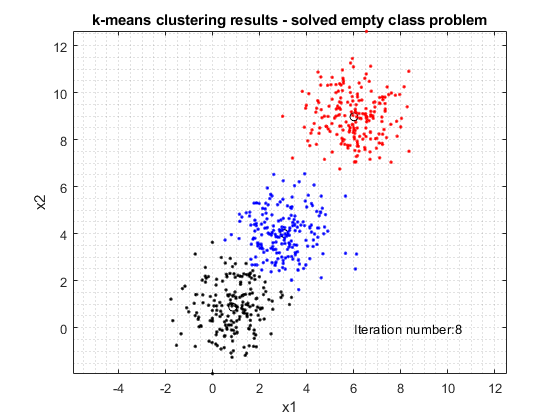

    if re_initilize == false
        break
    end

end

disp('Done')

Done


## Problem 3

### Subproblem 1

"Use the following code to generate a data set and find two principal components (PC). Plot the PCs with the original data.  "

clear all;close all;clc
n = 500;
mu = [0 0]; % mean values
sigma = [3 1.5; % standard deviation
        1.5 1];
X = mvnrnd(mu,sigma,n);
plot(X(:,1),X(:,2),'.')
hold on
grid minor
xlabel('x1')
ylabel('x2')

S = (1/n)*X'*X;

% u: eigen vector
% d: eigen values 
[u,d] = eig(S);

We should sort and identify the eigen value d from maximum to minimum value.

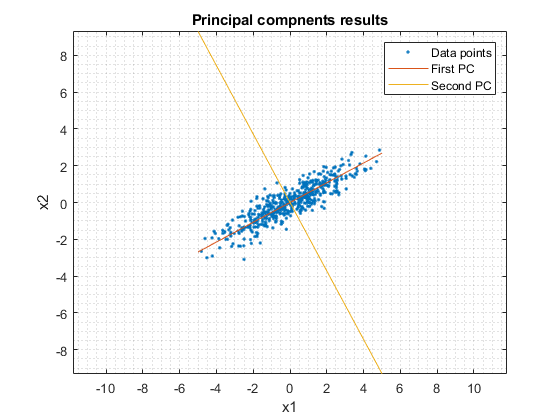

[max_v max_idx] = max(max(d));
[min_v min_idx] = min(min(d));
% max_idx = sort(max_idx,'descend')

u1 = u(:,max_idx); % first principal component
u2 = u(:,min_idx);

plot([-5 5],[-5 5]*(-1)*u(1,1)/u(2,1))
plot([-5 5],[-5 5]*(-1)*u(1,2)/u(2,2))
axis equal
title('Principal compnents results')
legend('Data points','First PC','Second PC')

### Subproblem 2

"Use the following code to generate a data set and find the first two principal components (PC). Plot the PCs with the original data.   "

clear all;close all;clc

n = 500;
mu = [0 0 0]; % mean values
sigma = [3 1.5 0 ; % standard deviation
1.5 1 0
0 0 0.01];
X = mvnrnd(mu,sigma,n);
figure
plot3(X(:,1),X(:,2),X(:,3),'.')
hold on
grid minor
axis equal
xlabel('x1')
ylabel('x2')
zlabel('x3')
title('Principal component results')
hold on
S = (1/n)*X'*X;
% u: eigen vector
% d: eigen values 
[u,d] = eig(S)

u =     0.8837    0.4680   -0.0013
    0.4680   -0.8837   -0.0017
    0.0019   -0.0009    1.0000


d =     3.7352         0         0
         0    0.1951         0
         0         0    0.0109



[max_v max_idx] = max(max(d));
% max_idx = sort(max_idx,'descend')

if max_idx == 3
    second_pc = -1;
else
    second_pc = 1;
end
u1 = u(:,max_idx); % first principal component
u2 = u(:,max_idx+second_pc);


At this point, we get u1, u2 is the unit vector.

So I try to draw it as a 3d plane go through point = [0,0,0] and a normal vector (u1 and u2), as follows:

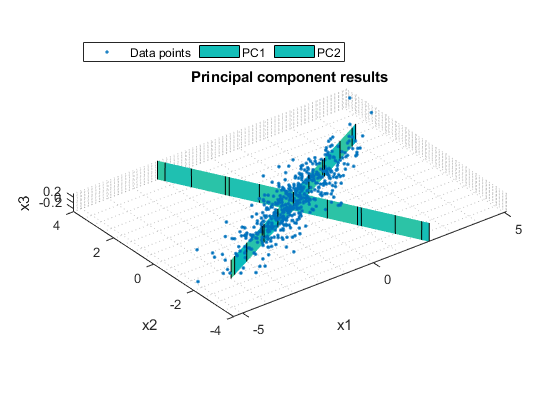

point = [0,0,0];
normal = u1';

d = -point*normal'; 

[xx,yy]=ndgrid(-4:4,-4:4);

z = (-normal(1)*xx - normal(2)*yy - d)/normal(3);

surf(xx,yy,z)
zlim([min(X(:,3)),max(X(:,3))])
hold on 
point = [0,0,0];
normal = u2';

d = -point*normal'; 

[xx,yy]=ndgrid(-4:4,-4:4);

z = (-normal(1)*xx - normal(2)*yy - d)/normal(3);

surf(xx,yy,z)
zlim([min(X(:,3)),max(X(:,3))])
legend('Data points','PC1', 'PC2','Location','northwest','Orientation','horizontal')

## Problem 4

### Subprolem 1

"Write an artificial neural network (ANN) code to classify the number data  "

First we create a sigmoid function

% function y = sigmoid_func(x)
%     y = 1./(1 + exp(-x));
% end

Then we create a softmax function

% function y = softmax_func(x)
%     exp_x = exp(x);
%     y = exp_x/ sum(exp_x);
% end

Now we prepare the dataset, as follow:

clearvars; clc; close all

numbers = zeros(5,5,5);
numbers(:,:,1) = [0 1 1 0 0
                  0 0 1 0 0
                  0 0 1 0 0
                  0 0 1 0 0
                  0 1 1 1 0];
numbers(:,:,2) = [1 1 1 1 0
                  0 0 0 0 1
                  0 1 1 1 0
                  1 0 0 0 0
                  1 1 1 1 1];
numbers(:,:,3) = [1 1 1 1 0
                  0 0 0 0 1
                  0 1 1 1 0
                  0 0 0 0 1
                  1 1 1 1 0];
numbers(:,:,4) = [0 0 0 1 0
                  0 0 1 1 0
                  0 1 0 1 0
                  1 1 1 1 1
                  0 0 0 1 0];
numbers(:,:,5) = [1 1 1 1 1
                  1 0 0 0 0
                  1 1 1 1 0
                  0 0 0 0 1
                  1 1 1 1 0];
              
data_x = zeros(25,5);

Visualize our dataset

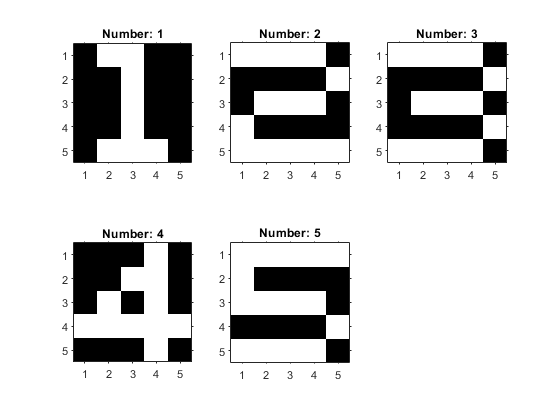

% figure('Position',[1 1 600 300])
for idx=1:5
    tmp = numbers(:,:,idx);
    data_x(:,idx) = tmp(:);
    subplot(2,3,idx)
    imshow(numbers(:,:,idx), 'InitialMagnification', 1500);
    axis on
    title(sprintf('Number: %g',idx))
end

Implement neuralnetwork

data_t = eye(5);
% initial random values assigned to weights
wji = 2*rand(50,25) - 1;
wkj = 2*rand(5,50) - 1;
rss_set = [];
for epoch=1:30
    [wji, wkj, rss] = backpropagation_number(wji,wkj,data_x,data_t);
    rss_set =[rss_set, rss];
  
end

Visualize loss evoluation

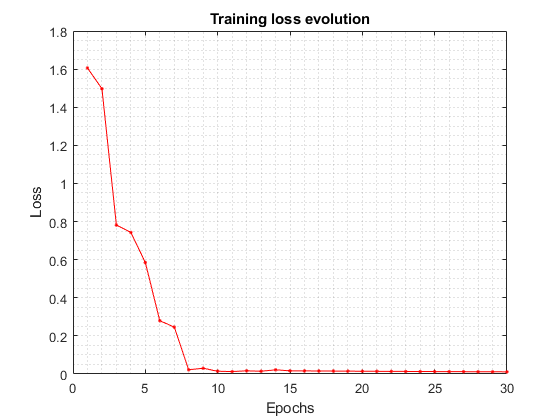

figure;
plot(rss_set,'r.-');
title('Training loss evolution')
xlabel('Epochs')
ylabel('Loss')
grid minor

Test the result

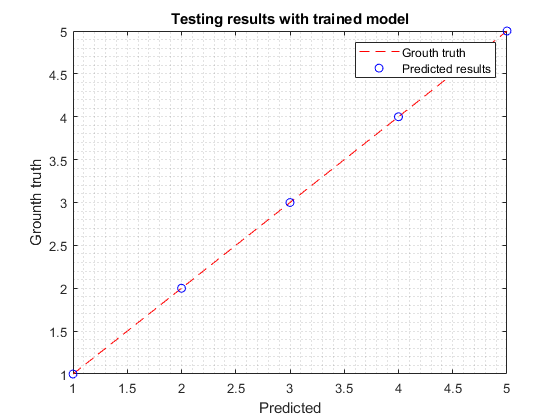

% feedforward
grouth_truth = [1:5];
figure
plot(grouth_truth,grouth_truth,'r--');
hold on 
for idx=1:5
    x = data_x(:,idx);
    y = sigmoid_func(wji*x);
    z = softmax_func(wkj*y);
    [z_max z_idx] = max(z);
    plot(z_idx,idx,'bo')
end
legend('Grouth truth','Predicted results')
xlabel('Predicted')
ylabel('Grounth truth')
title('Testing results with trained model')
grid minor

### Subproblem 2

"Add number 6 to your data. Train your ANN and show the test result. "

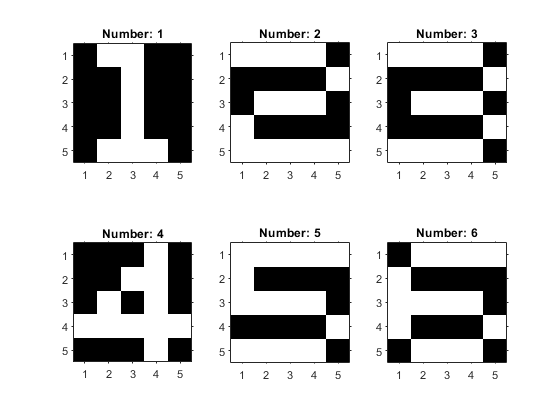

clearvars; clc; close all

numbers = zeros(5,5,6);
numbers(:,:,1) = [0 1 1 0 0
                  0 0 1 0 0
                  0 0 1 0 0
                  0 0 1 0 0
                  0 1 1 1 0];
numbers(:,:,2) = [1 1 1 1 0
                  0 0 0 0 1
                  0 1 1 1 0
                  1 0 0 0 0
                  1 1 1 1 1];
numbers(:,:,3) = [1 1 1 1 0
                  0 0 0 0 1
                  0 1 1 1 0
                  0 0 0 0 1
                  1 1 1 1 0];
numbers(:,:,4) = [0 0 0 1 0
                  0 0 1 1 0
                  0 1 0 1 0
                  1 1 1 1 1
                  0 0 0 1 0];
numbers(:,:,5) = [1 1 1 1 1
                  1 0 0 0 0
                  1 1 1 1 0
                  0 0 0 0 1
                  1 1 1 1 0];
numbers(:,:,6) = [0 1 1 1 1
                  1 0 0 0 0
                  1 1 1 1 0
                  1 0 0 0 1
                  0 1 1 1 0];
                  
data_x = zeros(25,6);

for idx=1:6
    tmp = numbers(:,:,idx);
    data_x(:,idx) = tmp(:);
    subplot(2,3,idx)
    imshow(numbers(:,:,idx), 'InitialMagnification', 1500);
    axis on
    title(sprintf('Number: %g',idx))
end

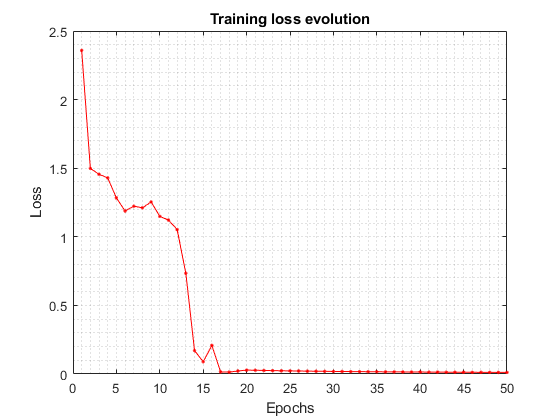

data_t = eye(6);

% initial random values assigned to weights
wji = 2*rand(50,25) - 1;
wkj = 2*rand(6,50) - 1;
rss_set = [];
for epoch=1:50
    [wji, wkj, rss] = backpropagation_number(wji,wkj,data_x,data_t);
    rss_set = [rss_set, rss];
end

figure;
plot(rss_set,'r.-');
title('Training loss evolution')
xlabel('Epochs')
ylabel('Loss')
grid minor

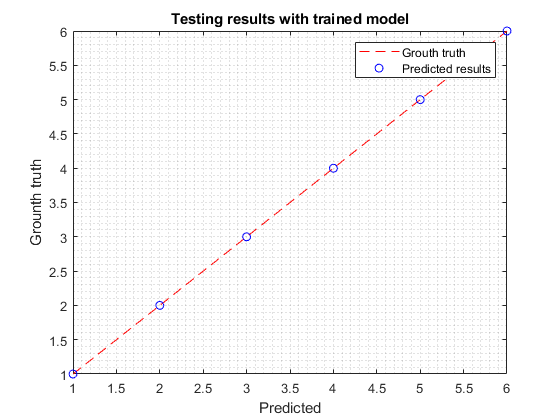

% feedforward
grouth_truth = [1:6];
figure
plot(grouth_truth,grouth_truth,'r--');
hold on 
for idx=1:6
    x = data_x(:,idx);
    y = sigmoid_func(wji*x);
    z = softmax_func(wkj*y);
    [z_max z_idx] = max(z);
    plot(z_idx,idx,'bo')
end
legend('Grouth truth','Predicted results')
xlabel('Predicted')
ylabel('Grounth truth')
title('Testing results with trained model')
grid minor